clearvars

Kris Keillor

Lab 2

Prof. Junaid Khan

EECE 360

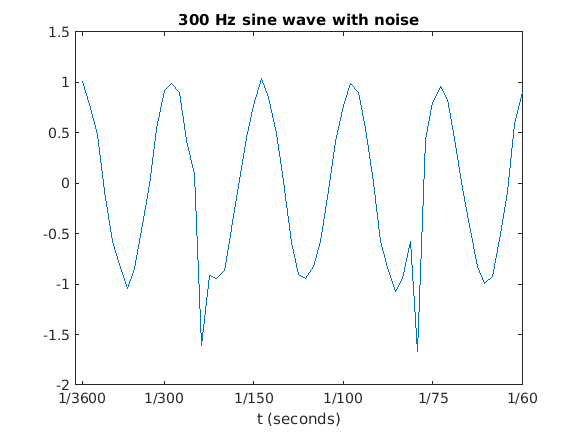

fs = 3600;
x = cosinegen(fs, 300, 60);
t=1:60;

x = addnoiseimpulse(x, 2, 2);
x = addnoisejitter(x, 0.1);

plot(t, x)
title("300 Hz sine wave with noise");
xticks([1 12 24 36 48 60])
xticklabels(["1/3600" "1/300" "1/150" "1/100" "1/75" "1/60"])
xlabel("t (seconds)")


dft_len = 60;

X = fft(x, dft_len)

X =   -3.6936 + 0.0000i   0.3318 - 1.1972i   2.6257 - 0.2619i  -0.4819 + 0.9228i  -3.0263 + 0.7721i  30.3787 - 0.8614i   3.0468 - 0.1991i  -0.6217 + 0.7338i  -1.7970 + 0.7954i   1.0784 - 0.3266i   2.4937 - 0.9827i  -1.2621 + 1.9110i  -1.9026 + 1.0781i   0.7936 - 1.3999i   1.5561 - 0.9668i  -1.1877 + 1.6406i  -1.1260 + 0.9742i   0.7463 - 1.6505i   0.9564 - 1.2425i  -1.4778 + 2.3570i  -0.9904 + 1.0356i   0.4434 - 2.2739i   1.0439 - 0.5121i  -0.3365 + 2.7250i  -0.4566 + 0.4358i   0.7088 - 3.0423i   0.3043 - 0.2620i  -0.1286 + 2.5940i  -0.2668 - 0.2282i   0.2896 - 2.7028i   0.5931 + 0.0000i   0.2896 + 2.7028i  -0.2668 + 0.2282i  -0.1286 - 2.5940i   0.3043 + 0.2620i   0.7088 + 3.0423i  -0.4566 - 0.4358i  -0.3365 - 2.7250i   1.0439 + 0.5121i   0.4434 + 2.2739i  -0.9904 - 1.0356i  -1.4778 - 2.3570i   0.9564 + 1.2425i   0.7463 + 1.6505i  -1.1260 - 0.9742i  -1.1877 - 1.6406i   1.5561 + 0.9668i   0.7936 + 1.3999i  -1.9026 - 1.0781i  -1.2621 - 1.9110i


X = abs(fftshift(X))

X =     0.5931    2.7183    0.3511    2.5972    0.4016    3.1238    0.6312    2.7457    1.1628    2.3167    1.4329    2.7820    1.5679    1.8114    1.4890    2.0254    1.8320    1.6092    2.1868    2.2901    2.6803    1.1268    1.9652    0.9617    3.0534   30.3909    3.1233    1.0411    2.6388    1.2424    3.6936    1.2424    2.6388    1.0411    3.1233   30.3909    3.0534    0.9617    1.9652    1.1268    2.6803    2.2901    2.1868    1.6092    1.8320    2.0254    1.4890    1.8114    1.5679    2.7820


stem(t, X)

% To label frequency bins 
% f = kFs/N Hz
k = (-dft_len/2:1:(dft_len/2)-1)

k =    -30   -29   -28   -27   -26   -25   -24   -23   -22   -21   -20   -19   -18   -17   -16   -15   -14   -13   -12   -11   -10    -9    -8    -7    -6    -5    -4    -3    -2    -1     0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19


f_bins = k.*fs/dft_len

f_bins =        -1800       -1740       -1680       -1620       -1560       -1500       -1440       -1380       -1320       -1260       -1200       -1140       -1080       -1020        -960        -900        -840        -780        -720        -660        -600        -540        -480        -420        -360        -300        -240        -180        -120         -60           0          60         120         180         240         300         360         420         480         540         600         660         720         780         840         900         960        1020        1080        1140



% indices for horizontal access labeled ticks
x_ax_ticks = [26 36]

x_ax_ticks =     26    36


num_labelled_ticks = length(x_ax_ticks)

num_labelled_ticks = 2

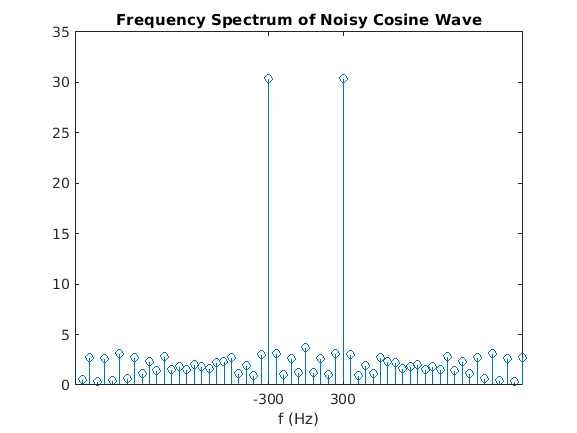


f_bins_labelled = zeros(num_labelled_ticks, 1);

for i = (1:1:num_labelled_ticks)
    f_i = x_ax_ticks(i);
    f_bins_labelled(i) = f_bins(f_i);
end

xticks(x_ax_ticks);
xticklabels(f_bins_labelled);
title("Frequency Spectrum of Noisy Cosine Wave");
xlabel("f (Hz)");

Exercise 2

t = 1:1:16;
signal = zeros(16, 1);
signal(1:1:8) = 1;
square_wave = signal'

square_wave =      1     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0


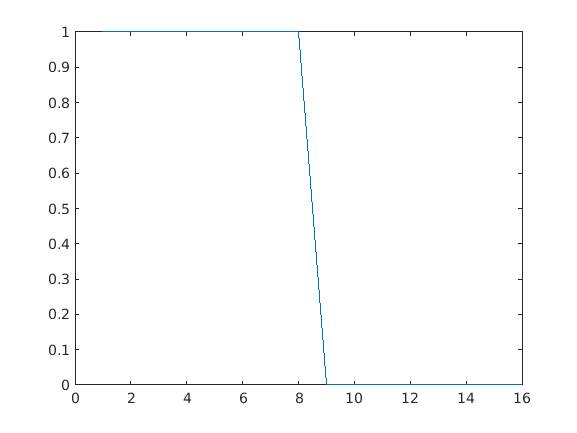


plot(t, square_wave)


fs = 16;
dft_len = 16;
% f = kFs/N Hz
k = (-dft_len/2:1:(dft_len/2)-1);
f_bins = k.*fs/dft_len

f_bins =     -8    -7    -6    -5    -4    -3    -2    -1     0     1     2     3     4     5     6     7



sq_wav_low_duty = square_wave;

for i = 8:-1:1
    subplot(2, 4, 9-i)
    Signal_F = abs(fftshift(fft(sq_wav_low_duty)))
    stem(t, Signal_F)
    if (i == 8)
        xticks([2 4 6 8 10 12 14 16]);
        xticklabels(["-7" "-5" "-3" "-1" "1" "3" "5" "7"])
    else
        xticks([]);
    end
    xlabel("f (Hz)")
    sq_wav_low_duty(i) = 0;
end

Signal_F =          0    1.0196         0    1.2027         0    1.8000         0    5.1258    8.0000    5.1258         0    1.8000         0    1.2027         0    1.0196


Signal_F =     1.0000    0.1989    1.0000    0.6682    1.0000    1.4966    1.0000    5.0273    7.0000    5.0273    1.0000    1.4966    1.0000    0.6682    1.0000    0.1989


Signal_F =          0    0.9420    0.7654    0.4602    1.4142    0.6888    1.8478    4.7357    6.0000    4.7357    1.8478    0.6888    1.4142    0.4602    0.7654    0.9420


Signal_F =     1.0000    0.5665    0.4142    1.1796    1.0000    0.3512    2.4142    4.2620    5.0000    4.2620    2.4142    0.3512    1.0000    1.1796    0.4142    0.5665


Signal_F =          0    0.7210    1.0824    0.8504         0    1.2728    2.6131    3.6245    4.0000    3.6245    2.6131    1.2728         0    0.8504    1.0824    0.7210


Signal_F =     1.0000    0.8478    0.4142    0.2346    1.0000    1.7654    2.4142    2.8478    3.0000    2.8478    2.4142    1.7654    1.0000    0.2346    0.4142    0.8478


Signal_F =          0    0.3902    0.7654    1.1111    1.4142    1.6629    1.8478    1.9616    2.0000    1.9616    1.8478    1.6629    1.4142    1.1111    0.7654    0.3902


Signal_F =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


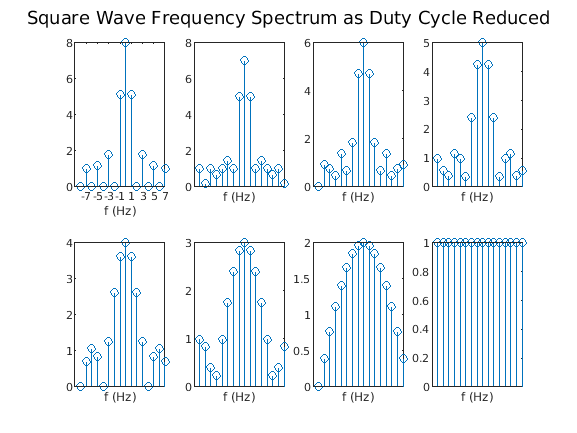


sgtitle("Square Wave Frequency Spectrum as Duty Cycle Reduced");
hold off

Exercise 3

subplot(1, 2, 1)
hn = [1 1 1 1]

hn =      1     1     1     1


yn = conv(hn, square_wave)

yn =      1     2     3     4     4     4     4     4     3     2     1     0     0     0     0     0     0     0     0



t19 = 1:1:19

t19 =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19


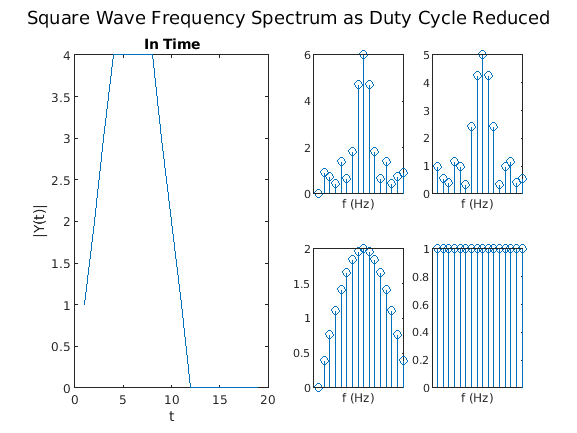

plot(t19, yn)
title("In Time")
xlabel("t")
ylabel("|Y(t)|")


SquareF = abs(fftshift(fft(yn)))

SquareF =     0.2008    0.8158    0.1956    1.0462    0.0987    1.0562    2.9743    4.3762   21.9781   32.0000   21.9781    4.3762    2.9743    1.0562    0.0987    1.0462    0.1956    0.8158    0.2008


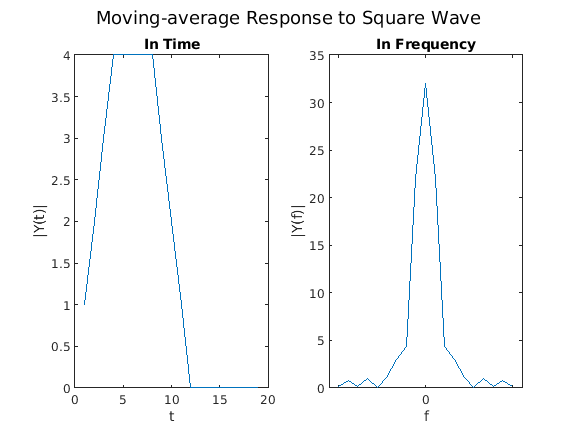

subplot(1, 2, 2)
plot(t19, SquareF)
title("In Frequency")
xlabel("f")
ylabel("|Y(f)|")
xticks([1 10 19]);
xticklabels(["" "0"])

sgtitle("Moving-average Response to Square Wave")
hold off

Ex 4

signal = zeros(16, 1);
signal(1:1:8) = 1;
square_wave = signal'

square_wave =      1     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0



iir_input_coeff =  [0.5 0    0     0      0       0 ]

iir_input_coeff =     0.5000         0         0         0         0         0


iir_memory_coeff = [0.5 0.25 0.125 0.0625 0.03125 0.015625]

iir_memory_coeff =     0.5000    0.2500    0.1250    0.0625    0.0312    0.0156


y = filter(iir_input_coeff, iir_memory_coeff, square_wave)

y =     1.0000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5156    0.5078   -0.4922    0.0078    0.0078    0.0078    0.0081    0.0079   -0.0077    0.0001


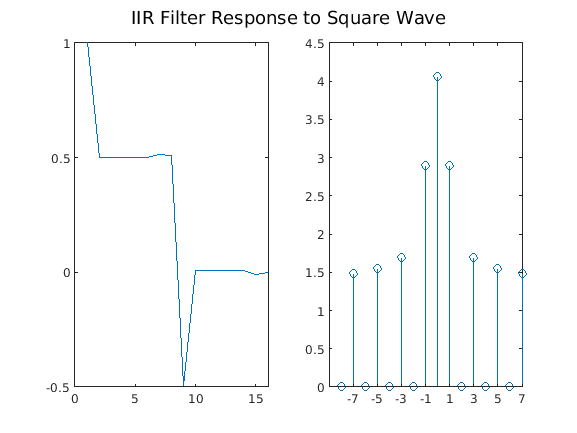

t_iir = 1:1:length(y);
subplot(1, 2, 1);

plot(t_iir, y);
title("In Time")
xlabel("t")
ylabel("|Y(t)|")

subplot(1, 2, 2);
stem(t_iir, abs(fftshift(fft(y))));
xticks([2 4 6 8 10 12 14 16]);
xticklabels(["-7" "-5" "-3" "-1" "1" "3" "5" "7"])
title("In Frequency")

sgtitle("IIR Filter Response to Square Wave")
hold off

Exercise 4 - Butterworth Filter

b = [0.0039 0.0193 0.0386 0.03860 0.0193 0.0039]

b =     0.0039    0.0193    0.0386    0.0386    0.0193    0.0039


a = [1     -2.3745 2.6360 -1.5664 0.4929 -0.0646]

a =     1.0000   -2.3745    2.6360   -1.5664    0.4929   -0.0646


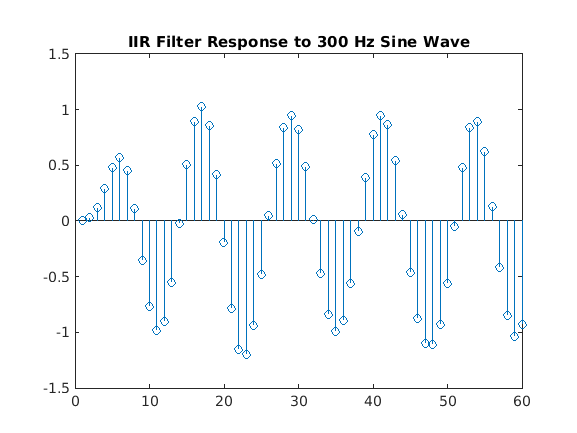


X_iir = filter(b, a, x);
t_X_iir = 1:1:length(X_iir);

subplot(1, 1, 1);
stem(t_X_iir, X_iir);
title("IIR Filter Response to 300 Hz Sine Wave");
sgtitle("");